options = trainingOptions('adam', ...
        'MaxEpochs',Maxepochs, ...
        'MiniBatchSize',miniBatchSize, ...
        'InitialLearnRate',learningrate, ...
        'LearnRateDropPeriod',10, ...
        'LearnRateDropFactor',0.75, ...
        'LearnRateSchedule','piecewise', ...
        'Plots','none',...
        'GradientThreshold',1, ...
        'shuffle','every-epoch',...
        'Verbose',0,...
        'DispatchInBackground',true);
    net = trainNetwork(XTrain,YTrain,layers,options);
    % evaluate
    YPred = classify(net, XTest, "MiniBatchSize",miniBatchSize);
    valError = 0;
    for k = 1:length(YPred)
    valError = valError + mean(YPred{k} == YTest{k});
    end
    accuracy = valError/length(YPred);
    TY = [];
    Y = [];
    YTest = YTest.';
    for k = 1:numel(YTest)
        TY = [TY;YTest{k}];
        Y = [Y;YPred{k}];
    end

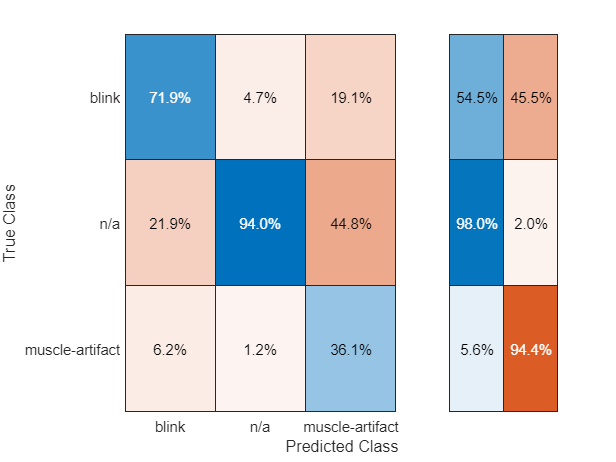

    confusionchart(TY(:),Y(:),'Normalization','column-normalized','RowSummary','row-normalized');